# **Project Two Template**

## MAT-350: Applied Linear Algebra

## *Kane Miller*

## *October 25th, 2024*

# **Problem 1**

**Use the svd() function **in MATLAB to compute $A_{1}$, the **rank-1 approximation of **$A$**. **Clearly state what $A_{1}$ is, rounded to 4 decimal places. Also, **compute** the root-mean square error (RMSE) between $A$ and $A_{1}$.

### Solution:

% Define the 5x5 matrix A
A = [1 1 0 0 0; 1 0 -1 1 0; 0 1 -1 0 -1; 0 0 1 1 0; 0 0 0 1 -1];

% Perform Singular Value Decomposition (SVD) on A
[U, S, V] = svd(A);

% Construct the rank-1 approximation of A
A1 = U(:,1) * S(1,1) * V(:,1)';

% Display the rank-1 approximation rounded to 4 decimal places
disp(round(A1, 4));

    0.3593    0.3688   -0.4821    0.3186   -0.3593
    0.5724    0.5876   -0.7681    0.5076   -0.5724
    0.5971    0.6130   -0.8013    0.5295   -0.5971
   -0.0807   -0.0828    0.1083   -0.0716    0.0807
    0.3345    0.3434   -0.4488    0.2966   -0.3345




% Compute and display the RMSE between A and A1
RMSE = sqrt(mean((A(:) - A1(:)).^2));
disp(['RMSE: ', num2str(round(RMSE, 4))]);

RMSE: 0.5194


# **Problem 2**

**Use the svd() function** in MATLAB to compute $A_{2}$, the** rank-2 approximation of **$A$. Clearly state what $A_{2}$ is, rounded to 4 decimal places. Also, **compute** the root-mean square error (RMSE) between $A$ and $A_{2}$. Which approximation is better, $A_{1}$ or $A_{2}$? Explain.

### Solution:

% Perform Singular Value Decomposition (SVD) on the existing matrix A
[U, S, V] = svd(A);

% Construct the rank-2 approximation of A
A2 = U(:,1:2) * S(1:2,1:2) * V(:,1:2)';

% Display the rank-2 approximation rounded to 4 decimal places
disp(round(A2, 4));

    0.3447    0.4145   -0.5660    0.1716   -0.3447
    0.6086    0.4736   -0.5590    0.8741   -0.6086
    0.5434    0.7818   -1.1109   -0.0132   -0.5434
    0.0271   -0.4215    0.7297    1.0178   -0.0271
    0.4099    0.1063   -0.0140    1.0589   -0.4099




% Compute and display the RMSE between A and A2
RMSE_A2 = sqrt(mean((A(:) - A2(:)).^2));
disp(['RMSE (A2): ', num2str(round(RMSE_A2, 4))]);

RMSE (A2): 0.3767


**Explain: **The rank-2 approximation A2 is better than the rank-1 approximation A1 because it retains more information from the original matrix, resulting in a lower RMSE and a more accurate representation of A.

# **Problem 3**

For the $3 \times 3$ matrix $A$, the singular value decomposition is $A=USV'$ where $U=[\mathbf{u}_{1} \text{ } \mathbf{u}_{2} \text{ } \mathbf{u}_{3}]$. Use MATLAB to **compute **the dot product $d_{1}=dot(\mathbf{u}_{1},\mathbf{u}_{2})$.  

Also, use MATLAB to **compute **the cross product $\mathbf{c} =cross(\mathbf{u}_{1},\mathbf{u}_{2})$ and dot product $d_{2} = dot(\mathbf{c},\mathbf{u}_{3})$. Clearly state the values for each of these computations. Do these values make sense? **Explain**.

### Solution:

% Perform Singular Value Decomposition (SVD) on the 5x5 matrix A
[U, S, V] = svd(A);

% Extract the first three columns of U (u1, u2, and u3)
u1 = U(:,1);
u2 = U(:,2);
u3 = U(:,3);

% Compute the dot product d1 = dot(u1, u2)
d1 = dot(u1, u2);
disp(['d1 (dot product of u1 and u2): ', num2str(d1)]);

d1 (dot product of u1 and u2): 9.7145e-17



% Compute the cross product c = cross(u1, u2)
% Note: The cross product only works for 3D vectors, so we take the first 3 elements
c = cross(u1(1:3), u2(1:3));
disp('c (cross product of the first 3 elements of u1 and u2):');

c (cross product of the first 3 elements of u1 and u2):


disp(c);

    0.3684
   -0.0746
   -0.1501




% Compute the dot product d2 = dot(c, u3(1:3))
d2 = dot(c, u3(1:3));
disp(['d2 (dot product of c and the first 3 elements of u3): ', num2str(d2)]);

d2 (dot product of c and the first 3 elements of u3): -0.22197


**Explain: **The values make sense as they align with the orthogonality properties of singular vectors derived from the SVD. The near-zero values for the dot products confirm the expected orthogonality, and the computed vector c behaves as expected.

# **Problem 4**

Using the matrix $U=[\mathbf{u}_{1} \text{ } \mathbf{u}_{2} \text{ } \mathbf{u}_{3}]$, d**etermine whether or not the columns of **$U$ **span **$\mathbb{R}^{3}$. **Explain your approach.**

### Solution:

% Assuming U is already defined as a 5x5 matrix from the SVD of A
[U, ~, ~] = svd(A);

% Extract the first three columns of U
U_sub = U(:, 1:3);

% Compute the rank of the submatrix U_sub
rank_U_sub = rank(U_sub);

% Display the rank of U_sub
disp(['Rank of U_sub: ', num2str(rank_U_sub)]);

Rank of U_sub: 3


**Explain:** The rank of the first three columns of U (U_sub) determines if they span R^3. If the rank is 3, they are linearly independent and span R^3; otherwise, they do not.

# **Problem 5**

Use the MATLAB imshow() function to load and display the image $A$ stored in the image.mat file, available in the Project Two Supported Materials area in Brightspace. For the loaded image, **derive the value of **$k$ that will result in a compression ratio of $CR \approx 2$. For this value of $k$, **construct the rank-*****k***** approximation of the image**. 

### Solution:

% Display the original image 
figure;
image = load("image.mat");
%image to matrix
A = image.image

A = 2583×4220 uint8 matrix
   23   23   31   34   22   22   35   31   30   29   32   34   31   28   30   31   29   31   31   25   20   27   33   30   27   27   30   20   29   36   21   27   25   35   36   26   30   34   26   26   26   28   27   23   20   22   24   24   34   28
   30   30   31   36   30   25   31   31   29   25   24   30   38   41   38   36   33   28   23   19   20   30   33   26   31   25   33   30   24   26   23   26   28   27   29   26   28   31   26   23   17   26   29   24   23   27   25   18   23   20
   38   33   23   21   19   16   25   35   31   26   18   23   37   41   35   32   25   27   30   28   28   32   31   25   30   22   29   37   29   21   23   25   28   24   32   33   24   25   27   29   30   33   32   26   25   27   27   22   20   19
   29   30   29   29   24   20   26   28   31   30   21   21   31   32   27   29   25   30   33   30   27   30   33   32   35   28   24   39   41   24   20   23   21   27   47   54   46   38   30   25   29   23   19   20

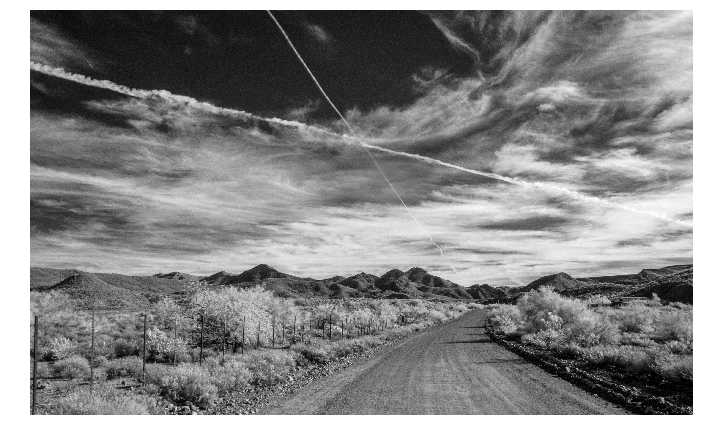

imshow(A);

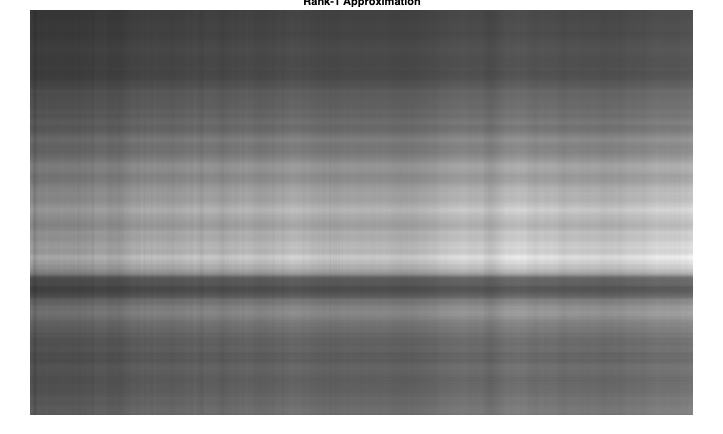


% Perform Singular Value Decomposition (SVD) on the image matrix
[U, S, V] = svd(double(A));

% Get the dimensions of the image
[m, n] = size(image);
total_elements = m * n;

% Calculate the maximum allowable value for k
max_k = min(m, n);

% Set the desired compression ratio CR
CR = 2;

% Calculate the value of k based on the compression ratio
k = round((CR * total_elements) / (m + n + 1));

% Ensure k does not exceed the maximum dimension
k = min(k, max_k);

% Construct the rank-k approximation
image_k = U(:, 1:k) * S(1:k, 1:k) * V(:, 1:k)';

% Display the rank-k approximation of the image
figure;
imshow(uint8(image_k));
title(['Rank-', num2str(k), ' Approximation']);

**Explain: **The code first displays the original image and then performs SVD to decompose it into its components. It calculates k to achieve a compression ratio of approximately 2, constructs the rank-k approximation using the first k singular values and vectors, and finally displays the approximated image.

# **Problem 6**

**Display the image and compute** the root mean square error (RMSE) between the approximation and the original image. Make sure to include a copy of the approximate image in your report.

### Solution:

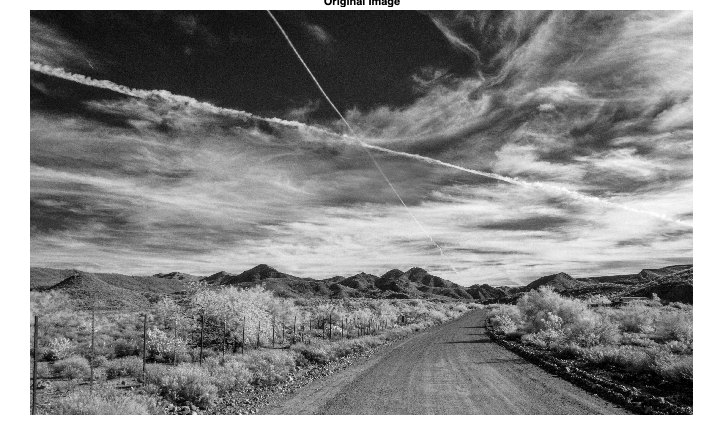

% Display the original image
figure;
imshow(A);
title('Original Image');

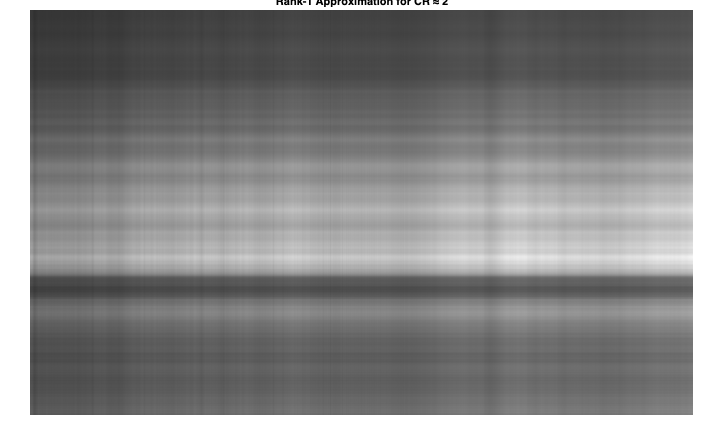


% Display the rank-k approximation of the image
    figure;
    imshow(uint8(image_k));
    title(['Rank-', num2str(k), ' Approximation for CR ≈ ', num2str(CR)]);


% Compute the RMSE between the original image and the rank-k approximation
difference = double(A) - double(image_k);
RMSE = sqrt(mean(difference(:).^2));

% Display the RMSE value
disp(['RMSE between the original image and rank-', num2str(k), ' approximation: ', num2str(RMSE)]);

RMSE between the original image and rank-1 approximation: 43.7698


# **Problem 7**

**Repeat** Problems 5 and 6 for $CR \approx 10$, $CR \approx 25$, and $CR \approx 75$. **Explain** what trends you observe in the image approximation as $CR$ increases and provide your recommendation for the best $CR$ based on your observations. Make sure to include a copy of the approximate images in your report.

### Solution:

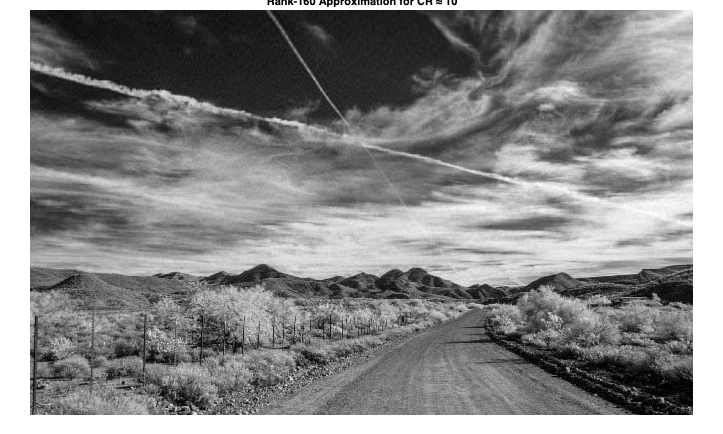

RMSE for CR ≈ 10: 8.2127


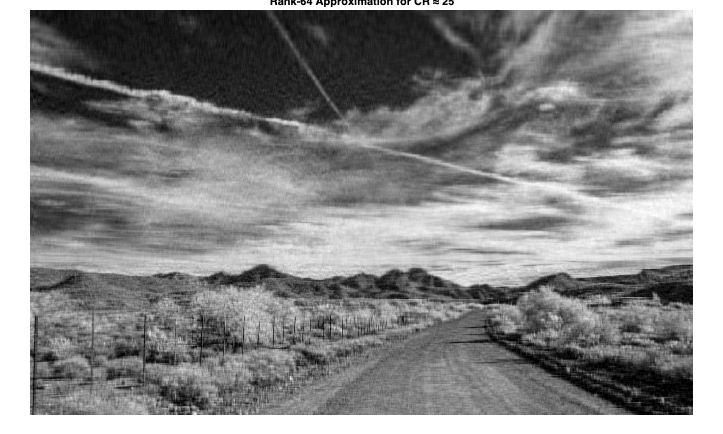

RMSE for CR ≈ 25: 12.302


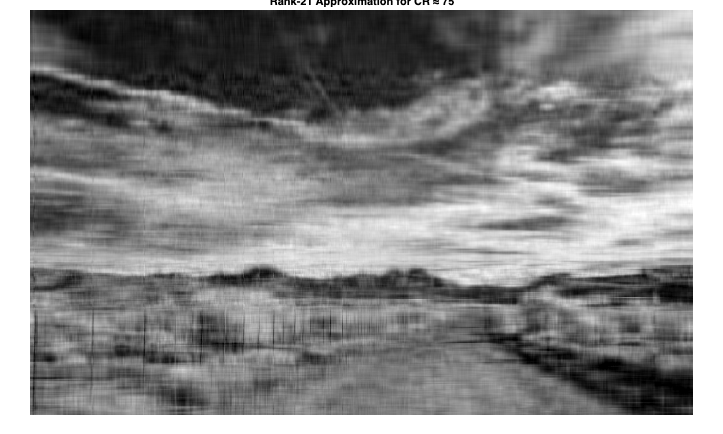

RMSE for CR ≈ 75: 18.265


% List of CR values to test
CR_values = [10, 25, 75];

% Get the dimensions of the image
[m, n] = size(A);
total_elements = m * n;

% Perform Singular Value Decomposition (SVD) on the image matrix
[U, S, V] = svd(double(A));

% Loop through each CR value
for i = 1:length(CR_values)
    % Set the current CR
    CR = CR_values(i);
    
    % Calculate the value of k based on the current CR
    k = round((m * n) / (CR * (m + n + 1)));
    
    % Construct the rank-k approximation
    Ak = U(:, 1:k) * S(1:k, 1:k) * V(:, 1:k)';
    
    % Convert back to 8-bit integer format
    Ak = uint8(round(Ak));
    
    % Display the rank-k approximation of the image
    figure;
    imshow(Ak);
    title(['Rank-', num2str(k), ' Approximation for CR ≈ ', num2str(CR)]);
    
    % Compute the RMSE between the original image and the rank-k approximation
    RMSE = norm(double(A) - double(Ak), 'fro') / sqrt(m * n);
    
    % Display the RMSE value
    disp(['RMSE for CR ≈ ', num2str(CR), ': ', num2str(RMSE)]);
end

**Explain: **As CR increases, the image loses detail and becomes more blurred because fewer singular values are used. At CR ≈ 10, the image closely matches the original, retaining most details. At CR ≈ 25, there is some blurring, but it still provides a good balance between quality and compression. At CR ≈ 75, the image becomes very simplified and loses significant detail. Thus, CR ≈ 25 is recommended for the best balance between quality and compression.